% Load the marker data
t = readtable("10Ax1.tsv", "FileType", "text", 'Delimiter', '\t');

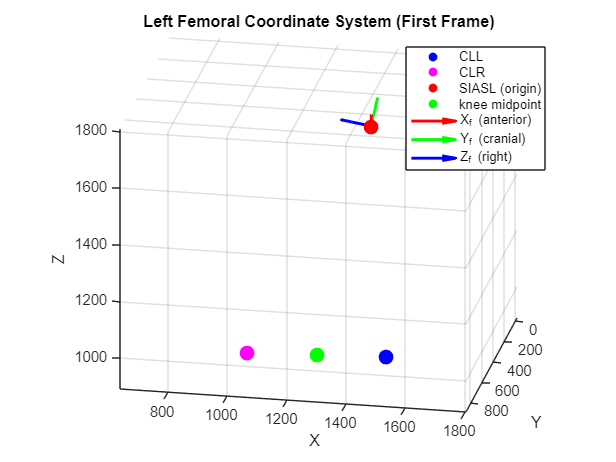


% Extract key marker positions (first frame)
CLL = [t.CLLX(1), t.CLLY(1), t.CLLZ(1)];   % Lateral femoral epicondyle
CLR = [t.CLRX(1), t.CLRY(1), t.CLRZ(1)];   % Medial femoral epicondyle
SIASL = [t.SIASLX(1), t.SIASLY(1), t.SIASLZ(1)];  % Left hip (origin)

% Midpoint between femoral epicondyles
knee_midpoint = (CLL + CLR) / 2;

% Build coordinate system
Y_f = SIASL - knee_midpoint;
Y_f = Y_f / norm(Y_f);

v1 = CLL - SIASL;
v2 = CLR - SIASL;
plane_normal = cross(v1, v2);
Z_f = cross(Y_f, plane_normal);
Z_f = Z_f / norm(Z_f);

X_f = cross(Y_f, Z_f);
X_f = X_f / norm(X_f);

% The attitude matrix
F_left_thigh = [X_f', Y_f', Z_f']

% Visualization
figure;
hold on; grid on; axis equal;

% Scale factor for arrows
scale_factor = 100;

% Plot key landmarks
scatter3(CLL(1), CLL(2), CLL(3), 100, 'b', 'filled'); % CLL
scatter3(CLR(1), CLR(2), CLR(3), 100, 'm', 'filled'); % CLR
scatter3(SIASL(1), SIASL(2), SIASL(3), 100, 'r', 'filled'); % SIASL (origin)
scatter3(knee_midpoint(1), knee_midpoint(2), knee_midpoint(3), 100, 'g', 'filled'); % Knee midpoint

% Draw axes from SIASL (origin)
quiver3(SIASL(1), SIASL(2), SIASL(3), X_f(1)*scale_factor, X_f(2)*scale_factor, X_f(3)*scale_factor, 0, 'r', 'LineWidth', 2); % X_f (anterior)
quiver3(SIASL(1), SIASL(2), SIASL(3), Y_f(1)*scale_factor, Y_f(2)*scale_factor, Y_f(3)*scale_factor, 0, 'g', 'LineWidth', 2); % Y_f (cranial)
quiver3(SIASL(1), SIASL(2), SIASL(3), Z_f(1)*scale_factor, Z_f(2)*scale_factor, Z_f(3)*scale_factor, 0, 'b', 'LineWidth', 2); % Z_f (right)

% Labels and view settings
legend('CLL', 'CLR', 'SIASL (origin)', 'knee midpoint' ,'X_f (anterior)', 'Y_f (cranial)', 'Z_f (right)');
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Left Femoral Coordinate System (First Frame)');
view(3); % 3D perspective view
hold off;